%音声読み込み、メルスペクトグラム生成
[audioIn,fs] = audioread('test_dataset/2530_AV.wav');
S = melSpectrogram(audioIn,fs);

[numBands,numFrames] = size(S);
fprintf("Number of bandpass filters in filterbank: %d\n",numBands)

Number of bandpass filters in filterbank: 32


fprintf("Number of frames in spectrogram: %d\n",numFrames)

Number of frames in spectrogram: 2358


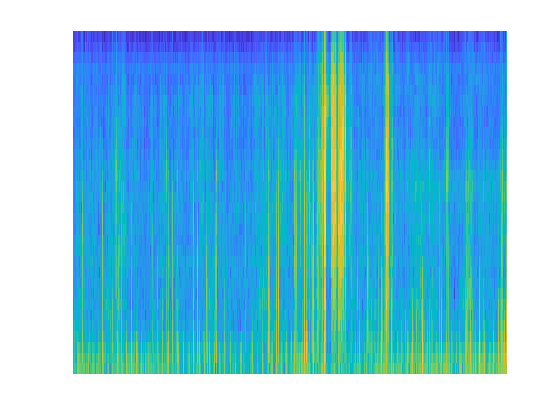

melSpectrogram(audioIn,fs)
ax = gca;
ax.YAxis.Visible = 'off';
ax.XAxis.Visible = 'off';
colorbar('off');

saveas(gcf,'chart.png')